# Single value decomposition

A = importdata('G:\My Drive\Research\Research Trips\2018 April Bern ISSI\Work\Oct 2019\xmm_corr.csv');

data = A.data;
nRec = size(data,1);
x = (rand(nRec,1)-0.5).*2;
A.colheaders

ans = 1×11 cell array
    {'count'}    {'Xgse'}    {'Ygse'}    {'Zgse'}    {'R'}    {'AE'}    {'Dst'}    {'f107'}    {'VxSW'}    {'NpSw'}    {'Pdyn'}


data(:,1) = log10(data(:,1));
normalizationParameter = [max(abs(data)),1];
B.colheaders = [A.colheaders,{'Rand'}];
B.dataNorm = [data,x]./normalizationParameter;
B.dataNorm(isnan(B.dataNorm)) = 0;
B.mean = nanmean(B.dataNorm);
B.min = min(B.dataNorm);
B.max = max(B.dataNorm);


## Covariance matrix

C = corr(B.dataNorm);
B.colheaders

ans = 1×12 cell array
    {'count'}    {'Xgse'}    {'Ygse'}    {'Zgse'}    {'R'}    {'AE'}    {'Dst'}    {'f107'}    {'VxSW'}    {'NpSw'}    {'Pdyn'}    {'Rand'}


C

C =     1.0000   -0.0611    0.0143    0.4048   -0.4084   -0.0155   -0.0094    0.0136   -0.1512   -0.1320   -0.0800   -0.0126
   -0.0611    1.0000   -0.1438   -0.1107    0.1184    0.1502   -0.0690   -0.5942    0.0920    0.0148   -0.0241   -0.0010
    0.0143   -0.1438    1.0000   -0.1456    0.1686   -0.0358    0.0074    0.1756    0.1461   -0.0030   -0.0349   -0.0066
    0.4048   -0.1107   -0.1456    1.0000   -0.9414   -0.0356    0.0366    0.0738    0.0965    0.0134   -0.0058   -0.0255
   -0.4084    0.1184    0.1686   -0.9414    1.0000    0.0724   -0.0650   -0.0694   -0.0866   -0.0170   -0.0026    0.0264
   -0.0155    0.1502   -0.0358   -0.0356    0.0724    1.0000   -0.5350   -0.0249   -0.1946    0.1032    0.2576    0.0064
   -0.0094   -0.0690    0.0074    0.0366   -0.0650   -0.5350    1.0000   -0.0935    0.2278    0.1931    0.0435   -0.0256
    0.0136   -0.5942    0.1756    0.0738   -0.0694   -0.0249   -0.0935    1.0000   -0.0082   -0.0723   -0.0893    0.0018
   -0.1512    0.0920    0.14

[1:12]

ans =      1     2     3     4     5     6     7     8     9    10    11    12


B.colheaders

ans = 1×12 cell array
    {'count'}    {'Xgse'}    {'Ygse'}    {'Zgse'}    {'R'}    {'AE'}    {'Dst'}    {'f107'}    {'VxSW'}    {'NpSw'}    {'Pdyn'}    {'Rand'}


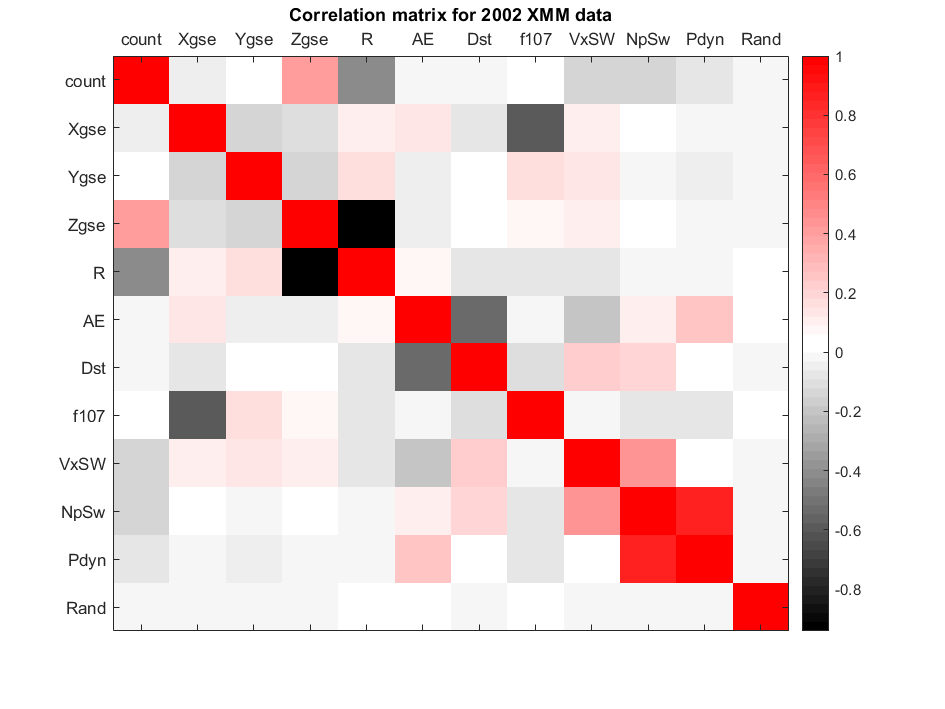

h = figure; 
resize_figure(h,150,200);
imagesc(C);
set(gca,'XTick',[1:13],'XTickLabel',B.colheaders,...
    'YTick',[1:13],'YTickLabel',B.colheaders,...
    'xaxisLocation','top');
colormap(get_colormap3('k','w','r'));
title('Correlation matrix for 2002 XMM data');
colorbar();


[U, S, V] = svd(B.dataNorm);
S

S =     0.4432         0         0         0         0         0         0         0         0         0         0         0
         0    0.3331         0         0         0         0         0         0         0         0         0         0
         0         0    0.1985         0         0         0         0         0         0         0         0         0
         0         0         0    0.0506         0         0         0         0         0         0         0         0
         0         0         0         0    0.0448         0         0         0         0         0         0         0
         0         0         0         0         0    0.0242         0         0         0         0         0         0
         0         0         0         0         0         0    0.0227         0         0         0         0         0
         0         0         0         0         0         0         0    0.0126         0         0         0         0
         0         0        